# DICOM Handling

The DICOM standard is widely used by the manufacturers of medical image scanners and suppliers of hospital PACs systems for transmitting, viewing and specifying medical images. The standard includes the format of medical image files.

### Organisation of information and images in a DICOM file

It is vital that images are correctly associated with the patient to which they belong. In DICOM, files contain both the image and associated information as meta-data. Examples of meta-data include scan date, patient name, age, position of the image within the patient, scanner details etc. The meta-data can be extracted from a DICOM file in MATLAB using `dicominfo` (and other methods discussed later). 

### The DICOM model of Patient, Study, Series, Instance

The terms "Study", "Series" and "Instance" have special meanings and relate to the DICOM model of a patient visit. A "Study" roughly corresponds to the whole session for a patient in a scanner. During this session there may be multiple "Series" acquired and each Series will contain one or more image "Instances". For example, the images used in an initial survey acquisition may be one Series, then in MRI a T1-weighted volume might be another Series and a T2-weighted volume another Series.

Different Unique Identifiers (UID)s are assigned to every Instance, Series and Study. These are usually long strings of numbers and dots. Their benefit is that they allow software to keep track of images, scans, sessions and patients. Series usually also get a text name to help identification e.g. "Survey", "T1W" 

There is no unique identifier for the patient. Within a clinical environment, identification usually involves at least patient name and date of birth.

### "Classic" and "Enhanced" DICOM

Throughout DICOM, it is useful to think of every image as just a 2D slice with information about its position in the meta-data. It is up to the user to assemble these images correctly in a 3D volume or a time series. In Classic DICOM, there is one image per file, whilst in Enhanced DICOM, there are multiple images in one file, usually there is one file for all the images in one Series. In MR, Enhanced DICOM also has more meta information about technical aspects of the scan. Enhanced DICOM has the advantages of more information and fewer files, however, the older Classic format can be read by all DICOM handling software. Enhanced DICOM is also called 'multiframe' because there are multiple frames in a single file. Note that 'frame' here means a single image and does not necessarily relate to a time frame.

### File naming and organisation

Although some software tries to name DICOM files and folders in meaningful ways, in general the filename conveys no useful information. You should not sort files or infer meaning from the filenames - instead the meta-data inside the files needs to be inspected. In Classic format, a patient Study with multiple volumes and time frames can result in thousands of images, each in a separate file and these files can be spread over multiple folders making handling difficult.  

### Handling DICOM folders and files

% Example use of dicomCollection and dicomBrowser
%
% The data is in-built with MATLAB
dataFolder = fullfile(matlabroot,"toolbox/images/imdata/") ;

% Make a MATLAB DICOM Collection, then open a dicomBrowser
dc = dicomCollection( dataFolder ) ;
dicomBrowser( dc )

Note that some DICOMs are just a single image (e.g. a plain X-ray) and some are volumes (e.g. most MR and CTs). The volumes can be in one multiframe file, or many single-frame files.

The variable `dc` here is a Table containing some meta-data. An example of viewing all rows and specified entries: 

dc(:,{'SeriesDateTime','SeriesDescription' ,'Rows','Columns','Frames'}) 

ans = 5×5 table
               SeriesDateTime         SeriesDescription    Rows    Columns    Frames
          ________________________    _________________    ____    _______    ______
    s1    {[30-Apr-1993 11:27:24]}    ""                   512       512         1  
    s2    {0×0 double            }    ""                     0         0         1  
    s3    {[03-Oct-2011 18:59:02]}    ""                   512       512         1  
    s4    {[03-Oct-2011 19:05:04]}    ""                   512       512         1  
    s5    {0×0 double            }    "PS LAX MR & AI"     430       600        10  

To pick out one Series, choose its row as the first index into the Table. e.g. 

dc("s3",:)

ans = 1×14 table
             StudyDateTime             SeriesDateTime         PatientName    PatientSex    Modality    Rows    Columns    Channels    Frames    StudyDescription    SeriesDescription                             StudyInstanceUID                                                     SeriesInstanceUID                                                         Filenames                            
          ____________________    ________________________    ___________    __________    ________    ____    _______    ________    ______    ________________    ____________

### Extracting Filenames from a MATLAB DICOM Collection

A dicom collection Table has a column 'Filenames' which contains the full names (including paths) of all the DICOM files associated with that Series (i.e. associated with that row of the Table). You can extract the filenames as follows:

% If dcClassic is a dicom collection for volumes from single-frame (Classic) DICOM files

% dcClassic.Filenames{"s2"}   % returns the filenames in a string array for Series s2 

% dcClassic.Filenames{"s2"}(3) % returns 1 filename for the 3rd file associated with Series s2

% If dcEnhanced is a dicom collection for volumes from multi-frame (Enhanced) DICOM files

% dcEnhanced.Filenames{"s2"} % returns the file name as a character vector 

% If dc is a dicom collection for a single image in single-frame (Classic) format

% dc.Filenames{"s1"}  % returns the file name as a character vector

### The MATLAB DICOM File Object

This offers a useful way to read, parse, modify and write DICOM files. It has useful associated object functions e.g. `findAttribute.` Note that the function `getPixelData` does **not** apply RescaleSlope if the attribute is not a top-level attribute (this can happen for Enhanced DICOMs). See Anonymisation section below.

### Viewing the meta-data

### Reading the image pixels

For a single frame file, `dicomread` returns the pixels for that file. For a multi-frame file, it returns all the frames. These can be sorted using information from `dicominfo`. For a **volume**, the function `dicomreadVolume `can read a volume, sort the slices into the correct order and also returns a structure with geometry information.

### Viewing Volumes using the Medical Image Toolbox

These functions only work for volumes (not single images). They require the Medical Imaging Toolbox.

There is also a function `medicalImage` but I have experienced problems with this. I also find `medicalVolume` difficult because it hides the orientation information and the pixels can be stored apparently rotated, leading to some confusion.

### Pixel Data Sizes and Types

Within a DICOM MR file, the pixel data is stored as integers and returned as type `int16`. Also, some attributes are read by MATLAB as integers. For many computations, it is safest to first convert these to type `double` to avoid inadvertent integer rounding (see below).

Some MATLAB functions use volumes of size [nrows ncols 1 nslices] with the '1' replaced by a '3' for RGB data. The function `dicomreadVolume` returns volumes using this format.

The user also needs to consider scaling:

### Scaling of data

Pixels are usually stored in DICOM as integers. If the underlying data is floating point or outside of the range of the integers used, then data might need to be linearly scaled using a `RescaleSlope` and `RescaleIntercept`. Typically this might be to get Hounsfield numbers in CT, or computed parameters in MR e.g. ADC diffusion values. In some DICOM files, the `RescaleSlope` and `RescaleIntercept` are replaced or complemented with `RealWorldValueMapping` parameters, which form a similar purpose, discussed later.

For the ankle CT data in the original dicomCollection

filenameAnkle = dc(contains(dc.Filenames, 'CT-MONO2-16-ankle.dcm'),:).Filenames ; 
dinfoAnkle = dicominfo( filenameAnkle ) ;

disp("Rescale Slope: " + dinfoAnkle.RescaleSlope + ...
     "    Intercept: " + dinfoAnkle.RescaleIntercept )

Rescale Slope: 1    Intercept: -1024


Now, we need to get the pixel data (which will be integers), and apply the rescaling to get Hounsield units. As the file is just one slice, we cannot use `dicomreadVolume` and need to use `dicomread`

img = dicomread(filenameAnkle) ;
whos img

  Name        Size              Bytes  Class    Attributes

  img       512x512            524288  int16              




% img is int16, convert to double, otherwise risk loss of precision, and
% rescale to Hounsfield units
imgHounsfield = (double(img) * dinfoAnkle.RescaleSlope) + dinfoAnkle.RescaleIntercept ;

hf = figure

hf =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties

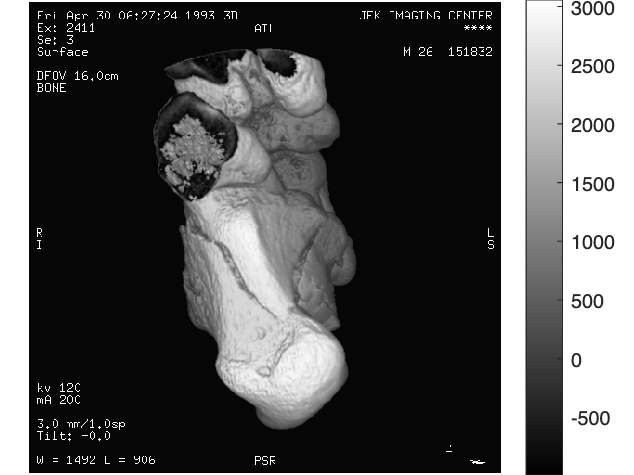

imshow(imgHounsfield,[]), colorbar

**BEWARE** when reading pixel data, or metadata from a file, that either may be read as an integer type, and if you multiply an integer with a doube in MATLAB it (annoyingly) returns an integer. Hence there is the risk of loss of precision. In the above, the `img` data had to be converetd to double before the rescale was applied.

### RescaleSlope and RealWorldValueSlope

In the above example, `RescaleSlope` and `RescaleIntercept` are top-level attributes. Sometimes in Enhanced DICOM, they can be hard to find, nested one per frame in the `PerFrameFunctionalGroupsSequence.` In this case, they can all be found by creating a `dicomFile` object and using `findAttribute(dFile,'RescaleSlope').`

Similarly, the `RealWorldValueSlope`  can be in the `SharedFunctionalGroupsSequence` and it can be located using `findAttribute(dFile,'RealWorldValueSlope').`

The DICOM standard allows for multiple RealWorldValue mappings, perhaps to map to different physical units.

In both cases, to get from the on-disk integer vaues to the floating point values, a linear mapping like the Hounsfield example above is used, i.e.  `floating_point_values = slope * double(Integer_values) + intercept`  

### Anonymisation and Protected Health Information

Anonymisation is also a complex topic. My current advice is that if possible, keep original, identifiable DICOMs direct from the scanner, in a safe location such as an encrypted hard drive, Data Safe Haven or Trusted Research Environment (TRE). Unless within a TRE, work on de-identified copies and try to avoid the NIfTI format. For de-identification, use quality software such as [DicomCleaner](http://www.dclunie.com/pixelmed/software/webstart/DicomCleanerUsage.html). For saving of intermediate results, use `.mat` files and include both the processed data, and a copy of the output of `dicominfo` that has been run on the de-identified data. If you have to use NIfTI, use a reliable convertor such as dcm2niix.

As stated, my preference for anonymisation is to use DicomCleaner. However, MATLAB can be useful for some manipulations. `dicomanon` will remove a pre-set list of attributes mentioned in the DICOM documentation . You can also specify attributes to keep or update. For example,

% To update a PatientName, keep a PatientID and anonymise many other
% attributes:

fileIn = filenameAnkle ;
fileOut = tempname ;

PatientName.FamilyName = 'Newname' ;
PatientName.GivenName = '';

attr_update.PatientName = PatientName ; % The updated attributes are fields
attr_keep = ["PatientID", "SeriesDescription"] ; % A string array

dicomanon(fileIn, fileOut, "update",attr_update, "keep", attr_keep)

The `updateAttribute` function can be used with a `dicomFile` object to change a specific attribute. Note this does not perform any further anonymisation amd will leave other attributes unchanged.

dFileIn = dicomFile(fileIn) ;

dFileNew = updateAttribute(dFileIn,'PatientName',PatientName) ;
write(dFileNew,fileOut)

### Comment

Reading DICOM data can be fiddly, sometimes needing trial and error. For example, in the above the filenames were in a cell array in one example, and not in another. Writing DICOM is harder, and can be a lot harder to get fully correct. Many people convert DICOM to NIfTI format but this has two major disadvantages. Firstly, a lot of software that uses NIfTI does not correctly handle geometry and you can end up with images are have slices reversed, flipped or transposed and this is both unsafe clinically and makes comparison with other clinical images error-prone. Second, the meta-data is no longer with the image (as NIfTI has only a brief header) so it might be difficult or error-prone to correlate image data with other patient data, for example histology results.

*David Atkinson.*

disp("Live Script last run: " + string(datetime("now")))

Live Script last run: 13-Oct-2024 21:07:05
